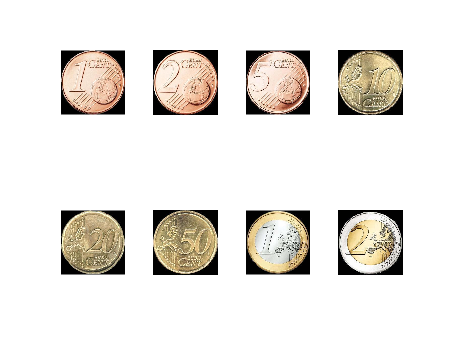

% Mehr Daten generieren
iterations = 1000;
for i = 1:8
    path = generateTestData(i-1, iterations);
    subplot(2,4,i);
    imshow(imread(path));
end

% Laden und Labeln
datasetPath = 'Dataset/';
imds = imageDatastore(datasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Unterteilen in Trainings- und Validierungsdaten
numTrainFiles = 750;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, 'randomized');

% Netzwerkarchitektur definieren
inputSize = [256 256 3];
numClasses = 8;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


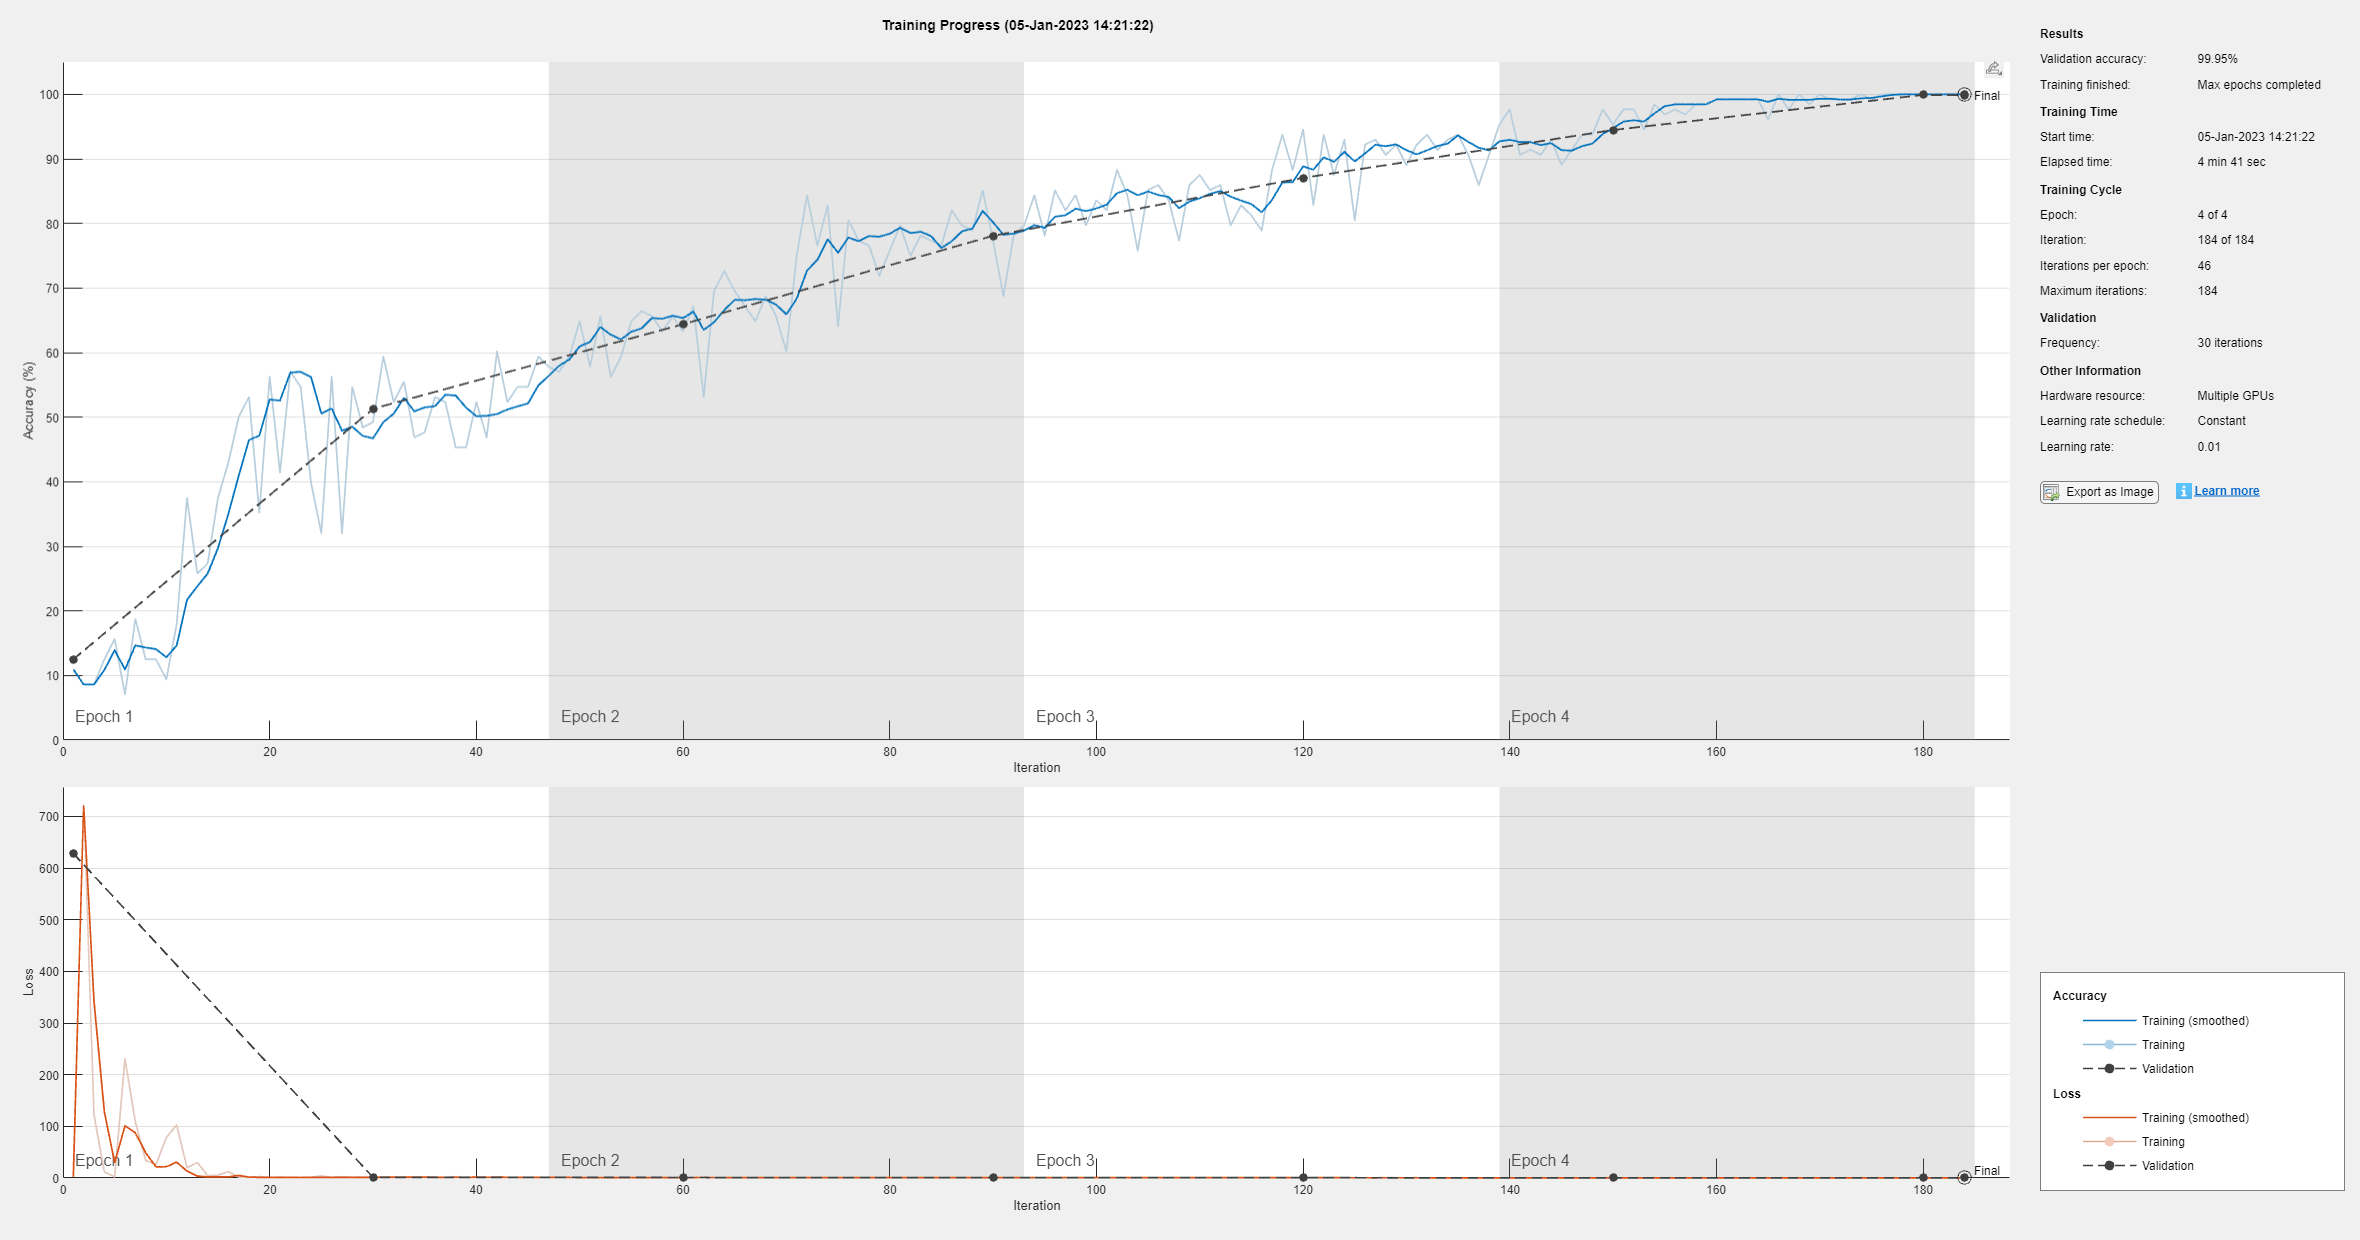

% Netzwerk trainieren
options = trainingOptions('sgdm', 'MaxEpochs', 4,'ValidationData', imdsValidation, ...
    'ValidationFrequency', 30, 'Verbose', false, 'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'parallel');

net = trainNetwork(imdsTrain, layers, options);

serializedNet = net;
save serializedNet;

% Netzwerk laden
load serializedNet
net = serializedNet;

% Netzwerk testen
YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9995

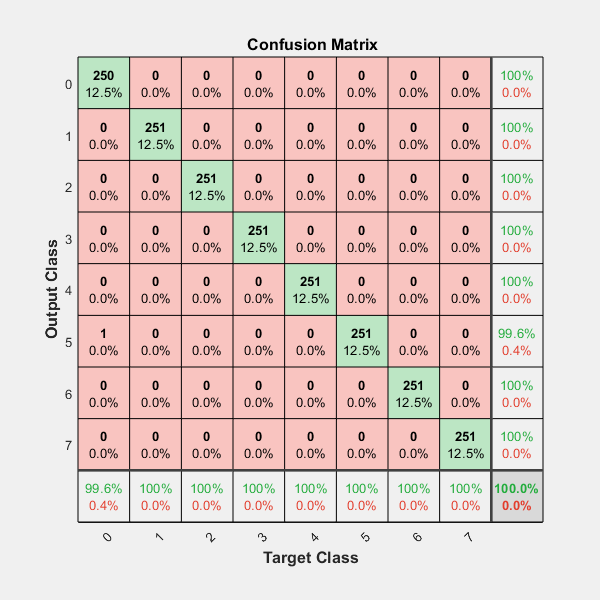

% plotconfusion(YValidation, YPred);


serializedNet = net;
% save serializedNet;

% Input-Bilder abgleichen
imdsTest = imageDatastore(fullfile('readCoins'), IncludeSubfolders=true);
% imdsTest = imdsValidation;
[YTest, scores] = classify(net, imdsTest);
scores

scores = 10×8 single matrix
    0.2088    0.0641    0.0693    0.2212    0.1354    0.1823    0.0600    0.0590
    0.0010    0.0000    0.0566    0.6537    0.0143    0.1992    0.0752    0.0000
    0.1227    0.0750    0.0201    0.1506    0.0853    0.5035    0.0200    0.0229
    0.0490    0.0004    0.0620    0.5094    0.0437    0.2382    0.0974    0.0000
    0.0000    0.0000    0.0144    0.8797    0.0003    0.0734    0.0322    0.0000
    0.2180    0.0593    0.0704    0.2226    0.1304    0.1845    0.0635    0.0515
    0.0974    0.0120    0.0880    0.3566    0.1179    0.2464    0.0814    0.0003
    0.0000    0.0000    0.0240    0.8303    0.0014    0.1000    0.0442    0.0000
    0.0307    0.0014    0.0869    0.4623    0.0766    0.2541    0.0879    0.0000
    0.0000    0.0000    0.0009    0.9827    0.0000    0.0093    0.0071         0


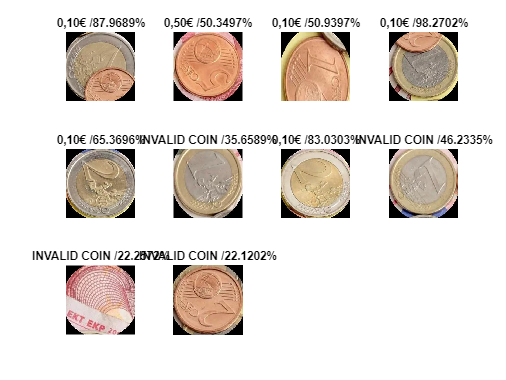

numImages = 10; %12 %10
idx = randperm(numel(imdsTest.Files), numImages);
tiledlayout('flow')
total = 0;
for i=1:numImages
    nexttile
    imshow(imdsTest.Files{idx(i)});  
    chance = max(scores(idx(i),:)) * 100;
    title(strcat(label2name(YTest(idx(i)), chance/100, t), ' / ', num2str(chance), '%'))
    total = total + label2decimal(YTest(idx(i)), chance/100, t);
    % Einspeisen ins Dictionary
end


display(strcat('Total:', sprintf('%0.2f', total), '€'));

Total:1.00€


function origPath = generateTestData(index, iterations)
    rng(0, 'twister');
    path = sprintf('Dataset/%01d/', index);
    origPath = strcat(path, 'orig.jpg');
    I = imresize(imread(origPath), [256 256]);
    imwrite(I, origPath, 'jpg');

    for i = 1:iterations
        angle = randi([0, 359],1,1);
        In = imrotate(I, angle);
        
        targetSize = [256 256];
        win = centerCropWindow2d(size(In), targetSize);
        In = imcrop(In, win);

        str = fullfile(path,  sprintf('generatedData_%03d.jpg', i));
        imwrite(In, str, 'jpg');
    end
end

function res = label2name(label, score, t)
    if (score < t)
        res = 'INVALID COIN';
    else
        switch (string(label))
            case '0'
                res = '0,01€';
            case '1'
                res = '0,02€';
            case '2'
                res = '0,05€';
            case '3'
                res = '0,10€';
            case '4'
                res = '0,20€';
            case '5'
                res = '0,50€';
            case '6'
                res = '1,00€';
            case '7'
                res = '2,00€';
        end
    end
end

function res = label2decimal(label, score, t)
    if (score < t)
        res = 0;
    else
        switch (string(label))
            case '0'
                res = 0.01;
            case '1'
                res = 0.02;
            case '2'
                res = 0.05;
            case '3'
                res = 0.1;
            case '4'
                res = 0.2;
            case '5'
                res = 0.5;
            case '6'
                res = 1;
            case '7'
                res = 2;
        end
    end
end